# GFDM System Simulation

% clear; clc; clf;
multiWaitbar('CLOSEALL');

## Debug mode

DEBUG = false;
PROGRESS_BAR = false;

Set the simulation parameters.

conste_size = 4;                  % Size of signal constellation (QPSK)
bits_per_sym = log2(conste_size); % Bits per symbol
Es = 1;                           % Symbol energy
EbN0 = (0:2:20);                  % Eb/N0

num_block = 1e5;          % Number of Monte Carlo trials(blocks)

GFDM parameters.

gfdm = struct;
gfdm.K = 8;                  % Subcarriers
gfdm.M = 7;                  % Subsymbols
gfdm.Kset = 0:7;         % Used subcarrier index

gfdm.pulse = 'dirichlet';    % Pulse shape
gfdm.Ncp = 0;                % CP length

gfdm.Kon = numel(gfdm.Kset); % Number of used subcarriers
gfdm.Mon = 7;                % Number of used used subsymbols
gfdm.D = gfdm.Kon*gfdm.Mon;  % Block size

Initialize prototype filters.

gfdm.g = dirichlet(gfdm.M, gfdm.K);
gfdm.A = g2A(gfdm.g, gfdm.K, gfdm.M);

if DEBUG
    % Plot A matrix
    X = 1:gfdm.D;
    figure;
    surf(X, X, abs(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('abs(A)');
    figure;
    surf(X, X, real(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('real(A)');
    figure;
    surf(X, X, imag(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('imag(A)');
end

GFDM simulation.

% Allocate space for transmit signals
sGFDM = zeros(num_block * gfdm.D, 1);
block_idx = 1;

if PROGRESS_BAR
    multiWaitbar('Total progress', 0/length(EbN0));
end

% BER estimation
ber_est = zeros(size(EbN0));

% Start timer
tic

for n = 1:length(EbN0)
    % Reset the error and bit counters
    num_errs = 0;
    num_bits = 0;
    
    parfor num_trial = 1:num_block
        % ---------- Tx ----------
        % Generate binary data and convert it to symbols
        tx_data = randi([0, 1], bits_per_sym, gfdm.D)';
        tx_data_symbol = bi2de(tx_data);
        
        % QPSK mapping
        qpsk_data = pskmod(tx_data_symbol, conste_size, pi/conste_size, 'gray');   % QPSK modulation with Gray coding
        % Normalize symbol energy
        qpsk_data_norm = (Es^0.5) * norm(qpsk_data(1)) * (qpsk_data);
        
        % Debug. Plot QPSK data:
        if DEBUG && n == 0
            scatterplot(qpsk_data_norm), grid;
            title('Constellation');
        end
        
        % Map QPSK data to actually used indices
        qpsk_data_map = map_KM(gfdm, qpsk_data_norm);
        % reshape the mapped data as a KxM matrix instead of a vector
        % qpsk_data_map_reshaped = reshape(qpsk_data_map, gfdm.K, gfdm.M);
        
        % GFDM modulation
        gfdm_data = gfdm.A * qpsk_data_map;
        
        % Cyclic prefix
        cp = gfdm_data(end-gfdm.Ncp+1: end);
        cp_data = [cp; gfdm_data];
        
        % Parallel to serial
        tx_sig = cp_data';
        
        % Store the transmit data
        % sGFDM((block_idx-1)*gfdm.D+(1:gfdm.D)) = qpsk_data_norm;
        
        % ----- Add AWGN noise -----
        snrdB = EbN0(n) + 10*log10(bits_per_sym); % Convert Eb/No to SNR
        rx_sig = awgn(tx_sig, snrdB);
        
        % ---------- Rx ----------
        %Serial to parallel
        rx_parallel = rx_sig';
        
        % Remove cyclic prefix
        rx_rm_cp_data = rx_parallel(gfdm.Ncp+1: end);
        
        % GFDM demodulation
        rx_demod_data = gfdm.A \ rx_rm_cp_data;
        % reshape the GFDM demod data as a KxM matrix instead of a vector
        % rx_demod_data_reshaped = reshape(rx_demod_data, gfdm.K, gfdm.M);
        
        % QPSK demodulation
        rx_data_symbol = pskdemod(rx_demod_data, conste_size, pi/conste_size, 'gray');
        % reshape the QPSK demod data as a KxM matrix instead of a vector
        % rx_data_symbol_reshaped = reshape(rx_data_symbol, gfdm.K, gfdm.M);
        
        % Keep only actually used indices
        rx_data_symbol_unmap = unmap_KM(gfdm, rx_data_symbol);
        
        % Convert symbols to bits
        rx_data = de2bi(rx_data_symbol_unmap, bits_per_sym);
        
        % Calculate the number of bit errors
        nErrors = biterr(tx_data, rx_data);
        
        % Increment the error and bit counters
        num_errs = num_errs + nErrors;
        num_bits = num_bits + gfdm.D*bits_per_sym;
                
        if PROGRESS_BAR
            multiWaitbar('Monte Carlo simulation', num_trial/num_block, 'Color', 'w');
        end
    end
    
    % Estimate BER
    ber_est(n) = num_errs/num_bits;
    
    if PROGRESS_BAR
        multiWaitbar('Total progress', n/length(EbN0), 'Color', 'w');
    end
end

if PROGRESS_BAR
    % Close progressbar
    multiWaitbar('CLOSEALL');
end

% End timer
toc

Elapsed time is 64.213134 seconds.


Plot PSD.

%f = linspace(-gfdm.K/2, gfdm.K/2, 2*length(gfdm.A)+1); f = f(1:end-1)';

Determine the theoretical BER curve by using the `berawgn` function.

berQPSK = berawgn(EbN0', 'psk', conste_size, 'nondiff');

Plot the estimated and theoretical BER data.

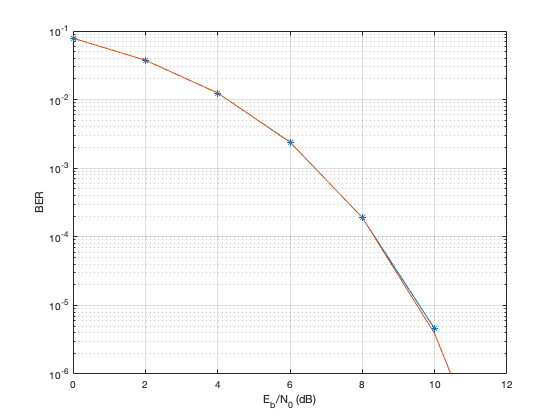

figure;
semilogy(EbN0, ber_est, '-*');
hold on;
grid;
semilogy(EbN0, berQPSK);
% legend('GFDM', 'QPSK');
% legend('$\mathcal{|K|}$ = 8', '$\mathcal{|K|}$ = 6', '$\mathcal{|K|}$ = 3', 'Interpreter','latex');
ylabel('BER');
ylim([10^(-6), 10^(-1)]);
xlabel('E_b/N_0 (dB)');